# Week03

Gemaakt door Nian Luisman

## Signal analysis

filename = "week3_sample_dist.wav"; % Name file.

[y_dist, fs] = audioread(filename); % Readfile
spec = fft(y_dist); 
N = length(spec); 
spec = spec / N; 
spec_positive = spec(1:N/2+1); 
freqs = (fs/N)*(0:N/2); 

% Plot de gegevens:
stem(freqs, abs(spec_positive)) 
xlabel("frequency (in Hz)") 
ylabel("Absolute value of the audio sample") 
title("Frequency spectrum of the audio file.")


## Low pass filter design

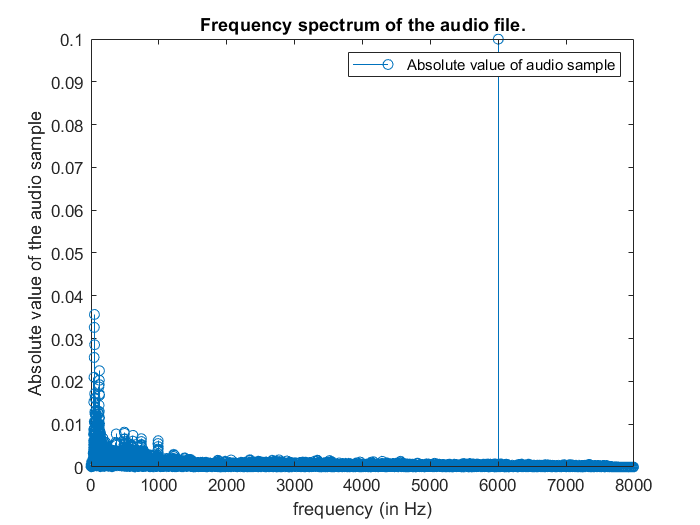

f_s = 16000; %Sample frequentie

f_c = 3000; % Kantelfrequentie 
T = 1/f_s;
tau = 1/(2*pi*f_c);

h_s = tf(1, [tau 1]); 
h_z_zoh = c2d(h_s, T, "zoh"); 


## Filtering

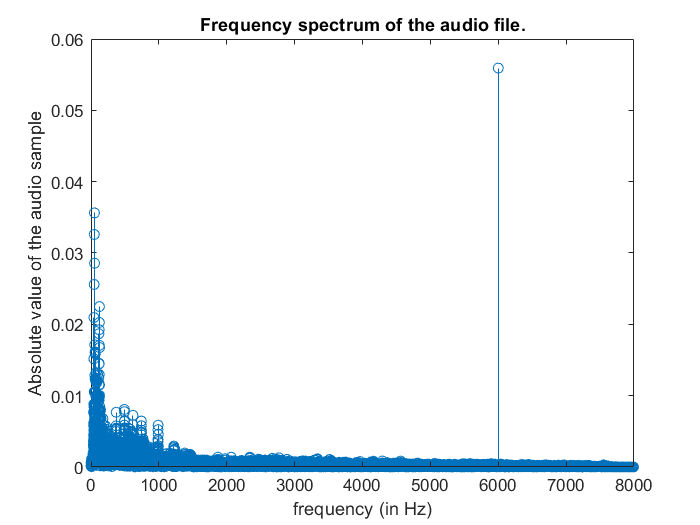

[x, fs] = audioread(filename);

y_dist = zeros(length(x), 1); .

y_dist(1) = 0; 


for i = 2:length(x)
    y_dist(i) = 0.3079*y_dist(i - 1) + 0.6921*x(i - 1); 
end

spec = fft(y_dist); 
N = length(spec); 
spec = spec / N;
spec_positive = spec(1:N/2+1); 
freqs = (fs/N)*(0:N/2);.


stem(freqs, abs(spec_positive)) 
xlabel("frequency (in Hz)") 
ylabel("Absolute value of the audio sample") 
title("Frequency spectrum of the audio file.") 